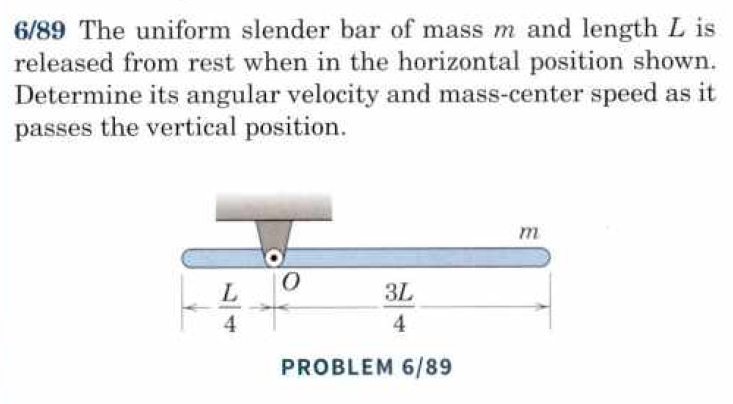

syms L m g omega_2 


d = L/4;
r = L/4;

Io = 1/12 * m*L^2 + d^2*m;

eq = m*g*L/4 == 1/2*Io*omega_2^2;

sol = simplify(solve(eq, omega_2))

$$sol = \left(\begin{array}{c} -\frac{2\,\sqrt{42}\,\sqrt{g}}{7\,\sqrt{L}}\\ \frac{2\,\sqrt{42}\,\sqrt{g}}{7\,\sqrt{L}} \end{array}\right)$$


a = sol(2)

$$a = \frac{2\,\sqrt{42}\,\sqrt{g}}{7\,\sqrt{L}}$$

b = sqrt(24*g/7*L)

$$b = \sqrt{\frac{24\,L\,g}{7}}$$


v = simplify(a*r)   

$$v = \frac{\sqrt{42}\,\sqrt{L}\,\sqrt{g}}{14}$$

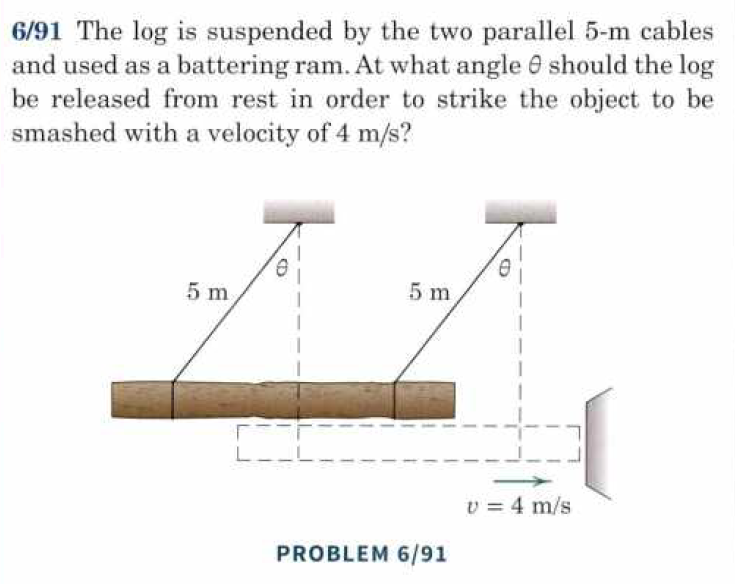

clear
u = symunit;
format short


v2 = 4;
g = 9.81;
L = 5;

theta = acos(1-v2^2/(2*g*L))

theta = 0.5792


rad2deg(theta)

ans = 33.1857

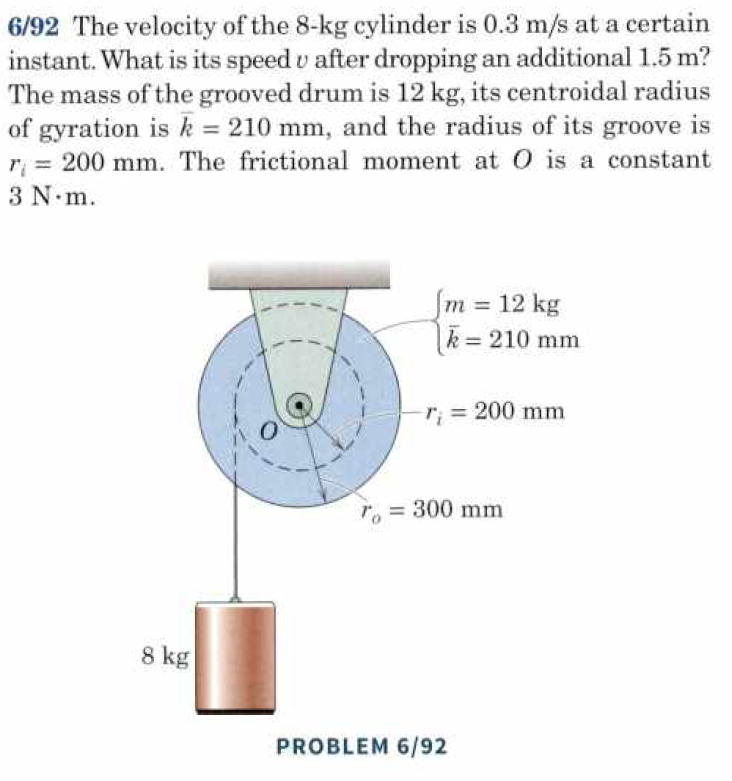

clear
u = symunit;

syms v2

g = 9.81*u.m/u.s^2

$$g = \frac{981}{100}\,\frac{m}{s^{2}}$$

v1 = 0.3*u.m/u.s;
ri = 200*u.mm; k = 210*u.mm; m_drum = 12*u.kg; my = 3*u.N*u.m; m_blok = 8*u.kg;

w1 = v1/ri;
w2 = v2/ri;

% r0 = 300*u.mm;
% D1 = r0*2
% 
% I1 = pi*D1^4/64;
% A1 = pi*D1^2/4;
% 
% D2 = ri*2;
% 
% I2 = pi*D2^4/64;
% A2 = pi*D2^2/4;
% 
% kny = sqrt((I1-I2)/A1) + sqrt(I2/A2);
% vpa(kny)


I0 = m_drum*k^2;

s = 1.5*u.m;

theta = s/ri;

my_M = theta*my;

eq = 1/2*m_blok*v1^2 + 1/2*I0*w1^2 + (m_blok*g*s - my_M) == 1/2*m_blok*v2^2 + 1/2*I0*w2^2;

v2 = solve(eq, v2);

v2 = vpa(simplify(unitConvert(v2, "SI")),5)

$$v2 = \left(\begin{array}{c} -3.01\,\frac{m}{s}\\ 3.01\,\frac{m}{s} \end{array}\right)$$



eq = 1/2*m_blok*v1^2 + 1/2*I0*w1^2

$$eq = \frac{19107}{20000}\,\frac{\mathrm{kg}\,m^{2}}{s^{2}}$$

vpa(eq, 3)

$$ans = 0.955\,\frac{\mathrm{kg}\,m^{2}}{s^{2}}$$